%% Task 2.1: Slicing the Data (com os nvos intervalos)

% --- 1. Z-Axis 30-70
idx_z = (t >= 35) & (t <= 70);
t_z     = t(idx_z);
p_z_data = pos(3, idx_z)';  
T_data   = u(1, idx_z)' + u(2, idx_z)' + u(3, idx_z)' + u(4, idx_z)'; 

% --- 2. X-Axis 75-100
idx_x = (t >= 75) & (t <= 100);
t_x     = t(idx_x);
p_x_data = pos(1, idx_x)';  
theta_data = lbd(2, idx_x)'; 

% --- 3. Y-Axis 100-135
idx_y = (t >= 105) & (t <= 135);
t_y     = t(idx_y);
p_y_data = pos(2, idx_y)';  
phi_data = lbd(1, idx_y)';   

disp('Data is sliced');

Data is sliced


disp('fim da 2.1')

fim da 2.1




%for the 2.2 we need to compare the input and outupts with the transfer
%function. This part is without matlab... meter no word as deduçoes 



%% Task 2.3: System Identification
disp('task 2.3')

task 2.3




data_x = iddata(p_x_data, theta_data, dt);
data_y = iddata(p_y_data, phi_data, dt);
data_z = iddata(p_z_data, T_data, dt);
% % remover o offset e vamos ver se usamos em todas
% data_x = detrend(data_x);
data_y = detrend(data_y);
% data_z = detrend(data_z);
%conclusao, nao usamos no x e z pq deu piores resultados 


% parte da tfest
np = 2; % Number of poles
nz = 0; % Number of zeros
%pq é o que nos esperamos ter


disp('buscar data ao log');

buscar data ao log


sys_id_x = tfest(data_x, np, nz);
sys_id_y = tfest(data_y, np, nz);
sys_id_z = tfest(data_z, np, nz);

% 3. Display the identified models
disp('--- Real world transfer functions from log< ---');

--- Real world transfer functions from log< ---


disp('Identified X-Axis TF (Pitch to X):');

Identified X-Axis TF (Pitch to X):


sys_id_x


sys_id_x =
 
  From input "u1" to output "y1":
          -7.845
  ----------------------
  s^2 + 0.025 s + 0.0103
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "data_x".
Fit to estimation data: 89.8%                      
FPE: 0.0005782, MSE: 0.0005773                     
 
Model Properties



disp('Identified Y-Axis TF (Roll to Y):');

Identified Y-Axis TF (Roll to Y):


sys_id_y


sys_id_y =
 
  From input "u1" to output "y1":
           -6.226
  ------------------------
  s^2 + 0.04836 s + 0.1052
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "data_y".
Fit to estimation data: 86.6%                      
FPE: 0.001029, MSE: 0.001028                       
 
Model Properties



disp('Identified Z-Axis TF (Thrust to Z):');

Identified Z-Axis TF (Thrust to Z):


sys_id_z


sys_id_z =
 
  From input "u1" to output "y1":
          0.03664
  -----------------------
  s^2 + 0.2803 s + 0.0838
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "data_z".
Fit to estimation data: 35.13%                     
FPE: 0.04657, MSE: 0.04652                         
 
Model Properties




%ok small comment on the results... The Y axis makes sense since the
%numerator is negative just like the theory. The biggest difference is the
%drag coef that is bigger 0.3 vs 0.15 and this means that the real drone
%gets more lateral drag

%the x axis is different since the numerator is negative. this is only a
%question of convection of the vectors

%the z axis is different. Besides the drag coef which is very similar 0.28
%vs 0.25, the other values are very different. The possible reason is the
%units. In the theoretical model, we used newtons but the real flight data
%used the values as dimentionless so this should be the reason.





disp('fim do 2.3')

fim do 2.3



%% Task 2.4: Model Evaluation (Comparing to Real Data)
disp('task 2.4 e ultima')

task 2.4 e ultima


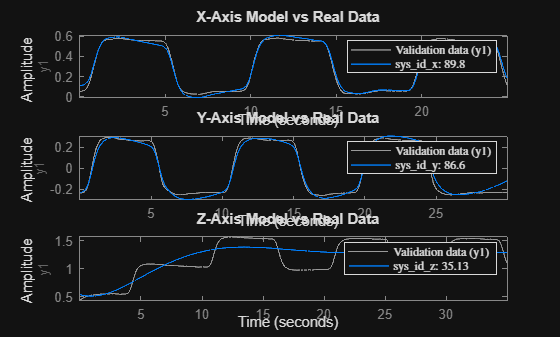

% fig com 3 subplot
figure('Name', 'System Identification Comparison');

% Compare X-Axis
subplot(3,1,1);
compare(data_x, sys_id_x);
title('X-Axis Model vs Real Data');

% Compare Y-Axis
subplot(3,1,2);
compare(data_y, sys_id_y);
title('Y-Axis Model vs Real Data');

% Compare Z-Axis
subplot(3,1,3);
compare(data_z, sys_id_z);
title('Z-Axis Model vs Real Data');